# **Homework 1 Orbital Dynamics**

Student 1: Mario Barrantes Mellado 100471762

Student 2: Artem Lorenzo Lymar 100471784

Data of the problem:

clear all; close all; clc;

m = 2000; % Mass of spacecraft - [kg]

phi_gs = deg2rad(50); % Angle of position of Ground Station w/ respect to equatorial plane - [rad]
h_gs = 0.8;  % Altitude of Ground Station (from Sea Level) - [km]
R_earth = 6371; % Radius of the Earth - [km]


mu_E = 3.986e5; % [km^3/m^2]
R_S = R_earth + h_gs; % Radius of Ground Station - [km]

t0 = 22.5; % [h]
ti = 9; % [h] - Time @ which spacecraft crossed equatorial plane
t = (t0 - ti)*3600; % Time since spacecraft crossed equatorial plane - [s]

r1 = [5369.09; 2332.14; 656.480]; % Initial position - [km]
v1 = [-3.37027; 4.90364; 0.106703]; % Initial velocity - [km/s]

### a) Expressing ECI base from SEZ base.

In this first section, the objective is to transform the position and velocity vectors that are initially expressed in the South-East-Zenith reference frame ($S_1$), i.e., the station-based reference frame,  into the Earth-Centered Inertial reference frame ($S_0$) . For doing this, the longitude and latitude rotations are performed inside the $SEZ2ECI$ function.

The rotation speed of S1 with respect to S0 is the one of the Earth (7.29216e-5 rad/s) and the latitude of the ground station ($\phi$) is 50º. The statement gives the position and velocity exactly at 22:30 (local time at the station), and the longitude angle ($\lambda$) can be obtained from knowing that the station crossed the Equatorial Plane ($\lambda=0$)  at 9:00.

[r0, v0, lambda, R_tot] = functionshw1.SEZ2ECI(r1, v1, R_S, phi_gs, t)

r0 = 1.0e+03 *

   -7.0281
   -5.5256
    1.9328


v0 =     4.6357
   -4.0404
    2.2481


lambda = 3.5440

R_tot =    -0.7049    0.3916   -0.5915
   -0.3000   -0.9201   -0.2517
   -0.6428         0    0.7660


### b) Classical orbital elements: $a$, $e$, $\Omega$, $i$, $\omega$ and $\theta_0$. Plot of orbit.

$rv2coe$ extracts the orbital elements from $r_0$ and $v_0$ using the angular momentum vector, the eccentricity vector, and atan2 projections to resolve quadrant ambiguities in $\Omega$, $\omega$ and $\theta_0$.

[a, e, Omega, i, omega, theta_0] = functionshw1.rv2coe(r0,v0,mu_E)

a = 9.0000e+03

e = 0.1000

Omega = 3.3258

i = 0.4363

omega = 2.3562

theta_0 = 4.4506

[Omega_deg, i_deg, omega_deg, theta_0_deg] = functionshw1.rad2deg(Omega, i, omega, theta_0)

Omega_deg = 190.5539

i_deg = 25.0000

omega_deg = 135.0005

theta_0_deg = 254.9995

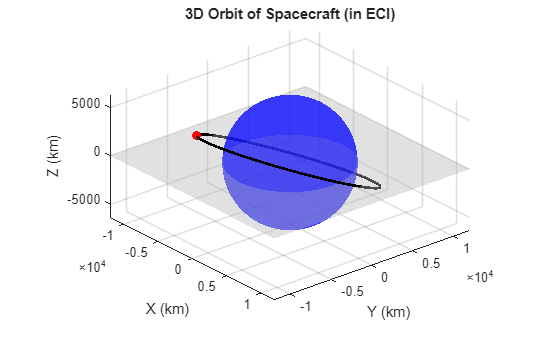

% Plot of orbit
theta = linspace(0,2*pi,200);
r = (a * (1 - e^2)) ./ (1 + e * cos(theta)); % Vector containing all positions across elliptical orbit

x_p = r .* cos(theta);
y_p = r .* sin(theta);
z_p = zeros(size(theta));

% Using the angles calculated by rv2coe
R = [cos(Omega)*cos(omega)-sin(Omega)*sin(omega)*cos(i), -cos(Omega)*sin(omega)-sin(Omega)*cos(omega)*cos(i),  sin(Omega)*sin(i);
     sin(Omega)*cos(omega)+cos(Omega)*sin(omega)*cos(i), -sin(Omega)*sin(omega)+cos(Omega)*cos(omega)*cos(i), -cos(Omega)*sin(i);
     sin(omega)*sin(i),                                   cos(omega)*sin(i),                                   cos(i)];

% Transform coordinates from perifocal to ECI frame
r_orbit = R * [x_p; y_p; z_p];

% Generate the Plot
figure;
plot3(r_orbit(1,:), r_orbit(2,:), r_orbit(3,:), 'LineWidth', 2, 'Color', 'k');
grid on; hold on;
axis equal;

% Earth build as a solid blue sphere
[sx, sy, sz] = sphere(50);
surf(sx*R_earth, sy*R_earth, sz*R_earth, 'FaceColor', 'blue', 'EdgeColor', 'none', 'FaceAlpha', 0.5); 

% initial position vector (r0) to verify it belows to the orbit
plot3(r0(1), r0(2), r0(3), 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 6);

% Adding Equatorial Plane - light grey plane
plane_limit = 12000; % Size of plane [km]
[X_eq, Y_eq] = meshgrid([-plane_limit plane_limit]);
Z_eq = zeros(size(X_eq)); % ploting plane exactly at Z = 0

% Plotting Earth surface - FaceAlpha makes it semi-transparent so the orbit
% can be seen acorss it
surf(X_eq, Y_eq, Z_eq, 'FaceColor', [0.7 0.7 0.7], 'EdgeColor', 'none', 'FaceAlpha', 0.4);

xlabel('X (km)'); 
ylabel('Y (km)'); 
zlabel('Z (km)');
title('3D Orbit of Spacecraft (in ECI)');
view(50, 25);

The resulting orbital elements, that come from the $rv2coe$ function, describe a nearly circular orbit ($e=0.1$) with a semi-major axis $a = 9000km$, placing the spacecraft already in MEO. The inclination of $i=25º$ creates a low-inclination orbit (as it can be seen by evaluating its inclination with respect to the equatorial plane that has been painted in light grey). The argument of perigee $\omega = 135º$ and true anomaly $\theta_0 \approx 255\degree $ indicates that at the moment of observation the spacecraft is past apocenter and approaching perigee. An additional check has been implemented: the initial position vector (red dot) lies exactly on the computed orbit, validating the $SEZ2ECI$ and $rv2coe$ functions.

### c) Local time at the station when the spacecraft reaches $\theta = \theta_0 + \pi/2$. Position and velocity of the spacecraft in ECI $6h$ after the initial observation. Position and velocity vectors of the spacecraft in SEZ at that instant.

delta_theta = pi/2;
n_e = sqrt(mu_E/a^3);

$deltatheta2t$ computes the true anomaly $\theta$ of the satellite for a given time, $theta2t$ does the inverse.

[t_f] = functionshw1.deltatheta2t(theta_0, delta_theta, mu_E, a, e, t0)

t_f = 23.0343

delta_t = 6; %[h]
[theta_f] = functionshw1.t2theta(theta_0, mu_E, a, e, delta_t) %[rad]

theta_f = 1.9599

$coe2rv$ computes position and velocity vectors in ECI by first computing them in the perifocal frame and then rotating ECI through $R_{rot}=R_{\Omega} R_i   R_{\omega}$

[rf_0, vf_0]  = functionshw1.coe2rv(a, e, Omega, i, omega, theta_f, mu_E)

rf_0 = 1.0e+03 *

    2.0961
    8.2669
   -3.6107


vf_0 =    -6.1079
    1.6782
   -1.2910


tf = (t0 + delta_t - ti)*3600; % Time since spacecraft crossed equatorial plane - [s]

$ECI2SEZ$ performs the inverse rotation of $SEZ2ECI$: the rotation matrix is simply transposed and Earth's rotation is removed from the velocity before projecting into SEZ reference frame.

[rf_1, vf_1, v1_0] = functionshw1.ECI2SEZ(rf_0, vf_0, R_S, phi_gs, tf)

rf_1 = 1.0e+04 *

   -0.2860
    0.5195
   -1.3485


vf_1 =    -1.9114
   -4.4528
   -3.2891


v1_0 =    -5.5051
    1.5253
   -1.2910


### d) Payload of 500kg released after 6h with velocity $\bar{v} = [-6.0, 3, -1.6] \ \text{km/s}$

For solving this section we will apply conservation of linear momentum: $$$m_{total} \vec{v}_{initial} = m_{sat} \vec{v}_{sat} + m_{payload} \vec{v}_{payload}$$$

m_payload = 500; % [kg]
m_sat_new = m - m_payload; % [kg] -> 1500 kg remaining

v_payload = [-6.0; 3.0; -1.6]; % [km/s] in ECI

% Conservation of Linear Momentum: m * vf_0 = m_sat * v_sat_new + m_payload * v_payload
v_sat_new = (m * vf_0 - m_payload * v_payload) / m_sat_new;

r_sat_new = rf_0; % since position doesn't change the instant the payload is released

% new classical orbital elements - rv2coe developed in question b)
[a_new, e_new, Omega_new, i_new, omega_new, theta_new] = functionshw1.rv2coe(r_sat_new, v_sat_new, mu_E);
[Omega_new_deg, i_new_deg, omega_new_deg, theta_new_deg] = functionshw1.rad2deg(Omega_new, i_new, omega_new, theta_new)

Omega_new_deg = 192.2394

i_new_deg = 25.3111

omega_new_deg = 91.1671

theta_new_deg = 154.6015

After the payload release, the spacecraft gains speed due to momentum conservation. This directly leads to resulting a decrease in its semi-major axis (9000 -> 8782 km) and lower eccentricity (from 0.1 to 0.061), meaning a slightly more circular orbit. The inclination and RAAN are almost unchanged, $\Delta i \approx 0.3^\circ$, $\Delta{\Omega} \approx 1.7^\circ$, as expected since the impulse is primarily along the orbit plane. The argument of perigee shifts significantly (from 135º to 91º), this is caused by the rotation of the eccentricity vector induced by the releasing of the payload, $\theta$ is also higly affected by this operation (almost 100º variation).

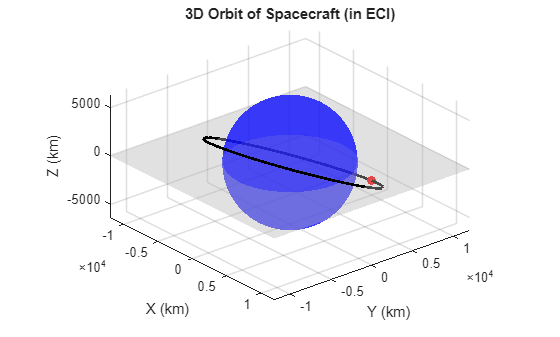

% plot of Earth and orbit after payload release
theta_plot = linspace(0,2*pi,200);
r = (a_new * (1 - e_new^2)) ./ (1 + e_new * cos(theta_plot)); % Vector containing all positions across elliptical orbit

x_p = r .* cos(theta_plot);
y_p = r .* sin(theta_plot);
z_p = zeros(size(theta_plot));

% Using rotation matrices calculated by rv2coe
R = [cos(Omega_new)*cos(omega_new)-sin(Omega_new)*sin(omega_new)*cos(i_new), -cos(Omega_new)*sin(omega_new)-sin(Omega_new)*cos(omega_new)*cos(i_new),  sin(Omega_new)*sin(i_new);
    sin(Omega_new)*cos(omega_new)+cos(Omega_new)*sin(omega_new)*cos(i_new), -sin(Omega_new)*sin(omega_new)+cos(Omega_new)*cos(omega_new)*cos(i_new), -cos(Omega_new)*sin(i_new);
    sin(omega_new)*sin(i_new),                                   cos(omega_new)*sin(i_new),                                   cos(i_new)];

% Transform coordinates from perifocal to ECI frame
r_orbit = R * [x_p; y_p; z_p];

figure;
plot3(r_orbit(1,:), r_orbit(2,:), r_orbit(3,:), 'LineWidth', 2, 'Color', 'k');
grid on; hold on;
axis equal;

[sx, sy, sz] = sphere(50);
surf(sx*R_earth, sy*R_earth, sz*R_earth, 'FaceColor', 'blue', 'EdgeColor', 'none', 'FaceAlpha', 0.5); 

% initial position vector to veriufy orbit
plot3(rf_0(1), rf_0(2), rf_0(3), 'ro', 'MarkerFaceColor', 'r', 'MarkerSize', 6);

% equaotrial plane
plane_limit = 12000;
[X_eq, Y_eq] = meshgrid([-plane_limit plane_limit]);
Z_eq = zeros(size(X_eq));

surf(X_eq, Y_eq, Z_eq, 'FaceColor', [0.7 0.7 0.7], 'EdgeColor', 'none', 'FaceAlpha', 0.4);

xlabel('X (km)'); 
ylabel('Y (km)'); 
zlabel('Z (km)');
title('3D Orbit of Spacecraft (in ECI)');
view(50, 25);

### e) ΔV required to circularize the orbit of the spacecraft at its new perigee

$coe2pa$ computes perigee and apocenter radii of any orbit from its semi-major axis and eccentricity as $r_p = a(1-e)$ and $r_a = a(1+e)$.

[rp_new, ra_new] = functionshw1.coe2pa(a_new, e_new)

rp_new = 8.2443e+03

ra_new = 9.3197e+03

From vis-viva equation we can get an equation for velocity: $\sqrt{\frac{2\mu_E}{r_{p_{new}}} - \frac{\mu_E}{a_{new}} }$, which if particularized for a circle (where $a=r_{pericenter}$) becomes $\sqrt{\frac{2\mu_E}{{a_{new}}} - \frac{\mu_E}{a_{new}} } = \sqrt{\frac{\mu_E}{a_{new}}}}$ . Then 

To circularize the orbit at perigee, the spacecraft must perform a burn opposite to the direction of its motion, since at that point its orbital velocity is greater than the needed to follow a circular orbit with the same radius. The required $\Delta V$ represents the magnitude of that velocity reduction, computed as: $\Delta{V}=V_{eliptical}-V_{circular} $ $\Delta V = v_{\text{pericentro}} - v_{\text{circular}} =      \sqrt{\frac{2\mu}{r_p} - \frac{\mu}{a}} - \sqrt{\frac{\mu}{r_p}} \approx 0.210      \text{ km/s}$. Yielding a positive scalar value that represents the cost of the maneuver, with the retrograde direction of the burn implied implicitly.

% Need to go from elliptical orbit to circular orbit when satellite is at the perigee
deltaV = sqrt((2*mu_E)/rp_new - mu_E/a_new) - sqrt(mu_E/rp_new) % [km/s]

deltaV = 0.2097

## Discussion

While solving this homework, from the very first moment the main challenge was correctly handling the reference frame transformations, ensuring the rotation matrices were applied in the right order and direction in $SEZ2ECI$ and $ECI2SEZ$ functions. Also, developing $rv2coe$ and $coe2rv$ functions was quite challenging at first, but once having realized some key lines they were straightly coded.

Results in section d are physically consistent since the orbit reduces its altitude after the releasing operation and from section e, the required $\Delta V$ to circularize the orbit is a reasonable value for a low-thrust maneuver in a spacecraft at this altitude.

## Copilot AI

Throughout the development of this homework, GitHub Copilot was primarily used to help in two tasks: errors detection and plots refinement. In all cases, the suggestions required revision such as renaming variables to adapt them to our code. Copilot was also suggesting incorrect orderings of the rotation matrices (R_omega·R_i·R_Omega instead of R_Omega·R_i·R_omega), which had to be corrected after cross-checking with the course notes. 

Overall, it is undeniable that Copilot has been very useful for speeding up boilerplate coding, but critical thinking was essential to validate and correct the outputs.